# Motivating example: Flow around an injection well

clc, close all, clear
set_demo_defaults()

Consider incompressible flow around a well with radius, $r_w$, injecting fluid at a constant rate, $Q_w$, into an aquifer with hydraulic conductivity $K$  (assumed to be isotropic and constant) and thickness $H$in a cylindrical domain with radius, $R$. The incompressible flow equation in coordinate-independent notation is given by


$$-\nabla\cdot\left[K\nabla h\right] = f_s$$


where $f_s$ is a source sink term assumed to be zero here. Instead we write the PDE in cylindrical coordinates, assuming circumfrential symetry, and represent the well as a boundary condition. The divergence and gradient in radial direction are given by

$\nabla\cdot =\frac{1}{r} \frac{\mathrm{d}}{\mathrm{d}r}r (\bullet)$ and $\nabla = \frac{\mathrm{d}}{\mathrm{d}x}$

so that we have the following problem

$-\frac{1}{r}\frac{\mathrm{d}}{\mathrm{d}r}\left[r\,K\frac{\mathrm{d}h}{\mathrm{d}r}\right] = 0$ for $r\in\left[r_w,\,R\right]
$ 

with the following flux boundary condition at the well


$$Q_w = A_w q_r(r=r_w) =-A_w K\left.\frac{\mathrm{d}h}{\mathrm{d}r}\right|_{r=r_w}$$
 

where $A_w = 2\pi r_w H$ is the area of the well-aquifer interface. This gives a condition on the derivative of $h$ at the well

$\left.\frac{\mathrm{d}h}{\mathrm{d}r}\right|_{r=r_w}=-\frac{Q_w}{A_wK}$.

At the far-field boundary we assume to have a constant head $h(r=R) = h_R$. The parameter values below are only for illustrative purposes.

param.rw = .1;   % well radius
param.r0 = 100;  % domain radius
param.h0 = 1;    % far-field head
param.Qw = 1;    % well flow rate
param.H = 1;     % aquifer thickness
param.K = 1;     % hydraulic conductivity
param.Aw = 2*pi*param.rw*param.H; % wellbore area
rlim = [param.rw,param.r0];

## Analytic solution

The analytic solution for this problem is obtained by integrating twice and is given by

$h(r) = h_0-\frac{Q_w}{2\pi H K}\ln\left(\frac{r}{R}\right)$,

$q_r(r) = \frac{Q_w}{2\pi H}\frac{1}{r}$,

$Q_w(r) = Q_w$,

The particular solution for the parameter values given above is shown in the first figure.

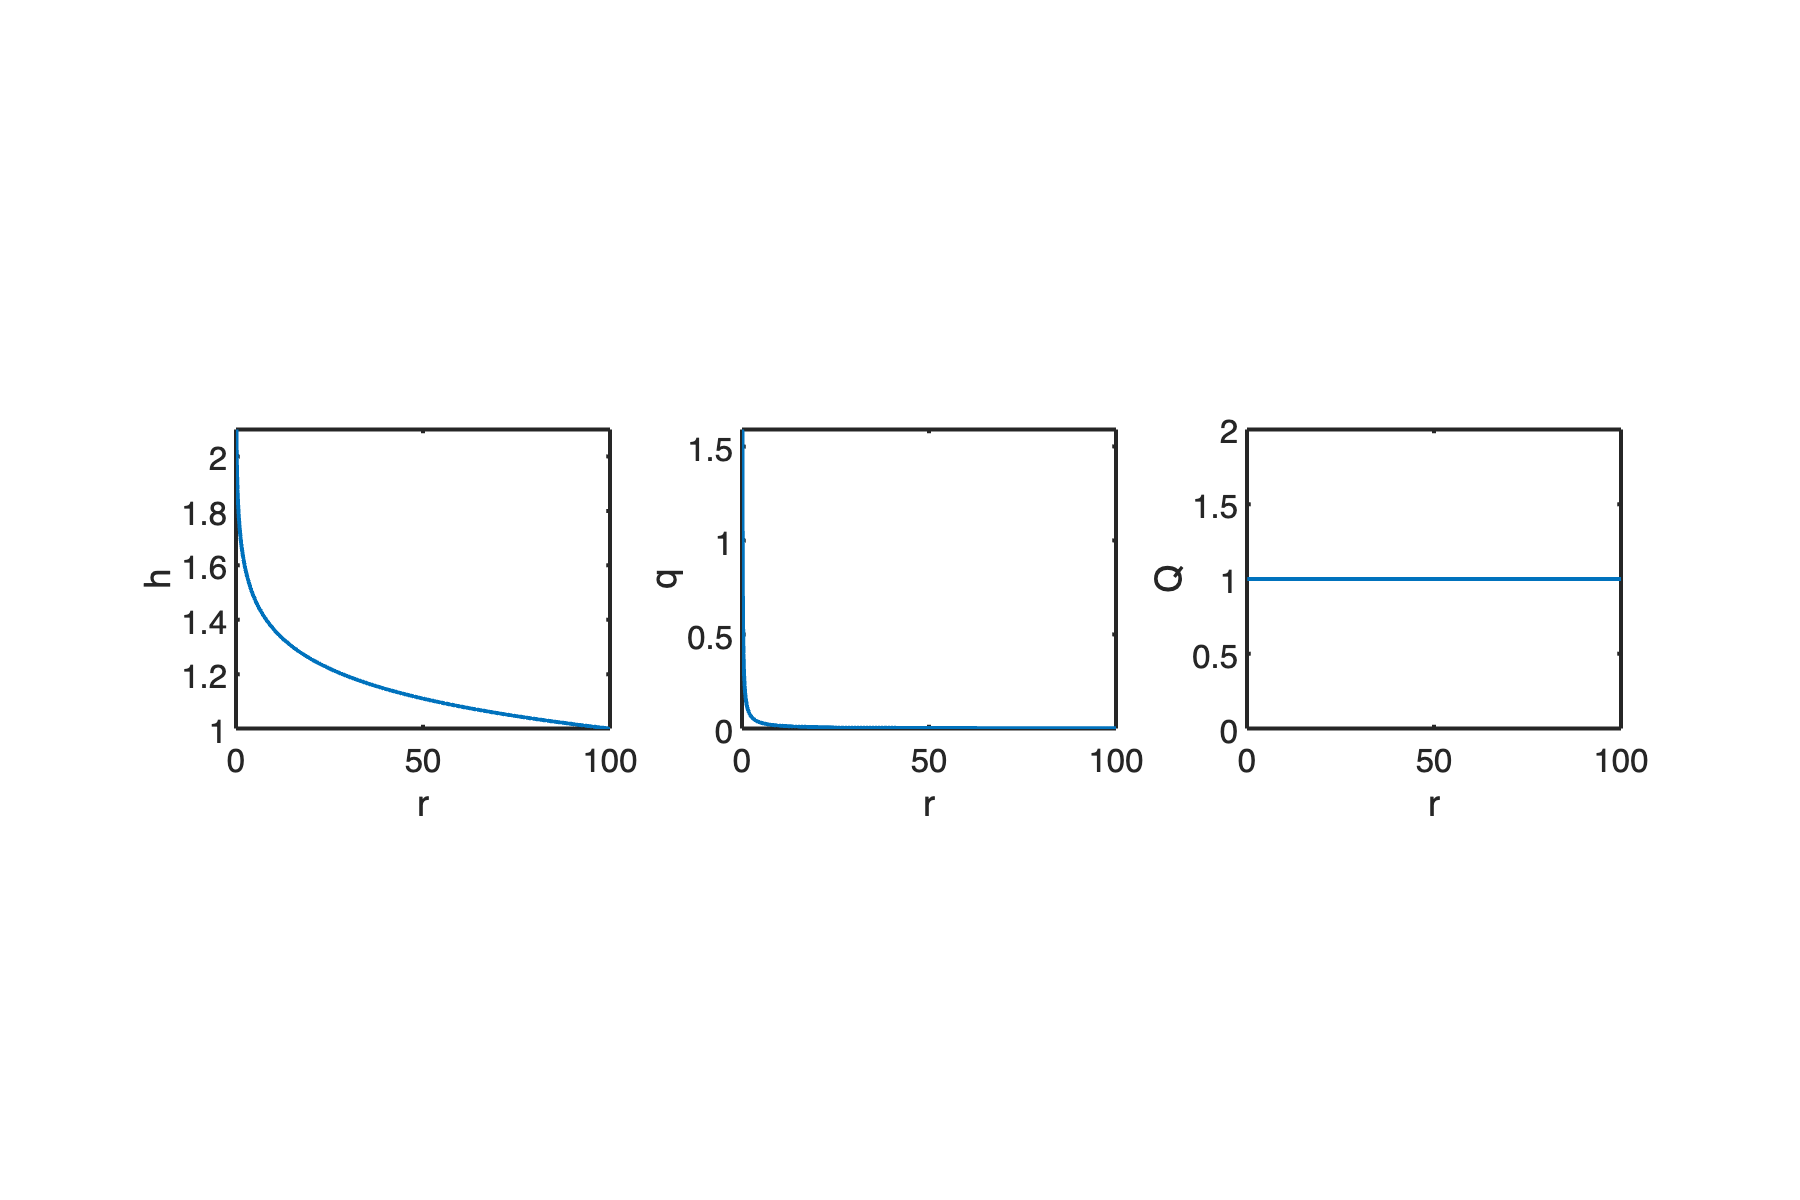

[xa,ha,qa,Qa] = AnalyticSolution(param);

figure('position',[10 10 900 600])
subplot 131
h = plot(xa,ha(xa),'-');
pbaspect([1 .8 1])
xlabel 'r', ylabel 'h'
subplot 132
plot(xa,qa(xa),'-')
pbaspect([1 .8 1])
xlabel 'r', ylabel 'q'
subplot 133
plot(xa,Qa(xa),'-')
pbaspect([1 .8 1])
xlabel 'r', ylabel 'Q'

This is a challenging solution due to the strong boundary layer at the well where the gradient of $h$ becomes very steep.

## 1) Standard finite difference approximation

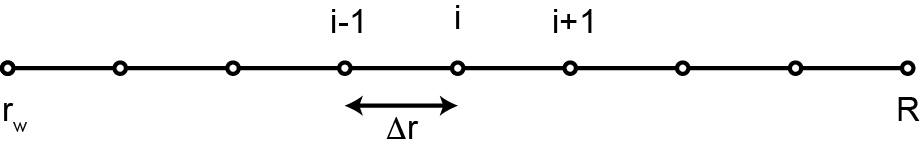

Above is a standard finite difference grid with node spacing $\Delta r$ and node index $i$. To use standard finite difference approximations for the first and second derivative we first need to expand the divergence


$$\frac{\mathrm{d}}{\mathrm{d}r}\left[r\frac{\mathrm{d}h}{\mathrm{d}r}\right] = r\frac{\mathrm{d}^2h}{\mathrm{d}r^2} + \frac{\mathrm{d}h}{\mathrm{d}r}$$


Then we can use the differentiation matrix, $\mathbf{D}$, to approximate the PDE as follows


$$r\frac{\mathrm{d}^2h}{\mathrm{d}r^2} + \frac{\mathrm{d}h}{\mathrm{d}r} \approx \left[\mathbf{R}*\mathbf{D}^2 + \mathbf{D}\right]*\mathbf{h}$$


where $\mathbf{R}$ is a diagonal matrix containing the position of the nodes and $\mathbf{h}$ is the discrete solution vector. This numerical solution is shown below.

param.Nx = 30; param.BC = 'ND';
[xFD,hFD,qFD,QFD] = FiniteDifferenceSolution(param,ha);

Unrecognized function or variable 'solve_lbvp'.

Error in demo_injection_well>FiniteDifferenceSolution (line 146)
hFD = solve_lbvp(L,fs,B,g,N);

figure('position',[10 10 900 600])
subplot 131
h = plot(xa,ha(xa),'-',xFD,hFD,'--'); hold on
c = get(h,'Color');
plot(rlim,ha(rlim),'o','markerfacecolor','w','markeredgecolor',c{1})
pbaspect([1 .8 1])
xlabel 'r', ylabel 'h'
legend('Analytic','FD')

subplot 132
title 'Standard finite differences'
plot(xa,qa(xa),'-',xFD,qFD,'--'), hold on
plot(rlim,qa(rlim),'o','markerfacecolor','w','markeredgecolor',c{1})
pbaspect([1 .8 1])
xlabel 'r', ylabel 'q'

subplot 133
plot(xa,Qa(xa),'-',xFD,QFD,'--'), hold on
plot(rlim,Qa(rlim),'o','markerfacecolor','w','markeredgecolor',c{1})
pbaspect([1 .8 1])
xlabel 'r', ylabel 'Q'

Observations:

- Standard finite differences lead to surprisingly large errors on the head, because we need to resolve the thin boundary layer near the well.

- The flow rate, $Q$, is not constant! **The mass of pore fluid is not conserved**. This will lead to wrong transport speeds for any solutes carried by fluid. 

Of course the colution will converge if the grid is refined sufficiently and mass balance errors will asymptote to zero. However, in practical simulations (2D or 3D) it is typically not possible to refine the grid sufficiently obtain acceptable errors.

## 2) Finite differencing in conservation form

In particular the coupling between transport of solutes or energy and fluid flow required that the numerical solution maintains discrete conservation. We loose the mass conservation in the standard finite difference discretization because we expand the divergence using the product rule. **We need to discretize the equation with the divergence intact**. 


$$-\nabla\cdot\left[K\nabla h\right] = -\frac{1}{r}\frac{\mathrm{d}}{\mathrm{d}r}\left[r\,K\frac{\mathrm{d}h}{\mathrm{d}r}\right] = 0$$


It helps to rewrite the *second-order* equation as a 'div-grad system' of two *first-order* equations for the head, $h$, and the radial component of the flux, $q_r$, as

- 
$$ \nabla\cdot\mathbf{q}=\frac{1}{r}\frac{\mathrm{d}}{\mathrm{d}r}\left[r\,q_r\right] = 0$$
 

- 
$$q_r = -K\nabla h= -K\frac{\mathrm{d}h}{\mathrm{d}r}$$


We discretize these equations on a co-located grid, where both $\mathbf{h}=h(\mathbf{x})$ and $\mathbf{q}=q_r(\mathbf{x})$ are approximated at the same nodes.

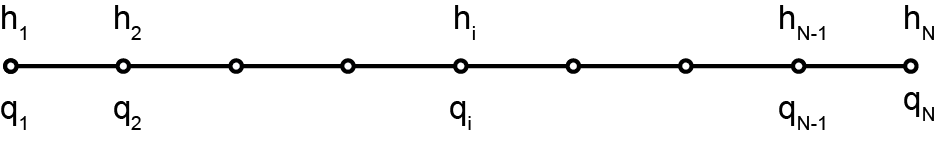

So we approximate the two first-order equations as

- $ \frac{\mathrm{d}}{\mathrm{d}r}\left[r\,q_r\right] \approx \frac{r_{i+1}q_{i+1}-r_{i-1}q_{i-1}}{2\Delta r}$,

- $ -K\frac{\mathrm{d}h}{\mathrm{d}r} \approx K_i\frac{h_{i+1}-h_{i-1}}{2\Delta r} = q_i$.

D*[R*D*h]

We can eliminate $q_i$ by substituting 2 into 1 to obtain


$$-\frac{1}{4\Delta r^2}\left[r_{i+1}K_{i+1}h_{i+2}-\left(r_{i+1}K_{i+1}+r_{i-1}K_{i-1}\right)h_i +r_{i-1}K_{i-1}h_{i-2}\right]$$


this *stencil* involves $h_{i-2}$, $h_i$ and $h_{i+2}$ and leads to a decoupling of the even and odd nodes

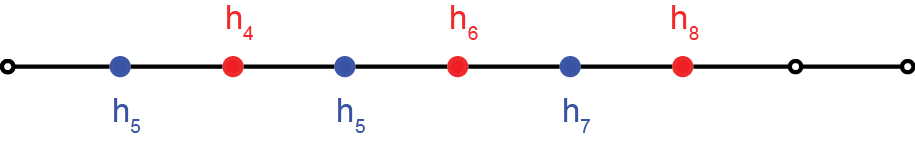

param.Nx = 30;
[x,h,q,Q,L,L_e_o] = FD_collocated(param,ha);

figure('position',[10 10 900 600])
plot(xa,ha(xa),'-'); hold on
plot(x,h)
xlabel 'r', ylabel 'h'
pbaspect([1 .8 1])
legend('Analytic','FD: 1st-order system')

This decoupling leads to oscillations between even and odd nodes. 

figure('position',[10 10 900 600])
subplot 121
spy(L)
title 'Standard ordering'
subplot 122
spy(L_e_o)
title 'Even-odd ordering'

## 3) Conservative Finite Differences (CFD)

Third time is the charm (hopefully). We stay with the equations in the 'div-grad form':

- 
$$ \nabla\cdot\mathbf{q}=\frac{1}{r}\frac{\mathrm{d}}{\mathrm{d}r}\left[r\,q_r\right] = 0$$
 

- 
$$q_r = -K\nabla h= -K\frac{\mathrm{d}h}{\mathrm{d}r}$$


However, we change from the **collocated** grid to a **staggered** grid to avoid the decoupling of the even and odd degrees of freedom.

On a staggered grid, where $\mathbf{h}=h(\mathbf{x}_c)$ and $\mathbf{q}=q_r(\mathbf{x}_f)$ are approximated at the different locations. We divide the domain into equal cells

and approximate the heads, $\mathbf{h}$, at the cell centers, $\mathbf{x}_c$, but approximate the fluxes, $\mathbf{q}
$, at cell faces, $\mathbf{x}_f$.

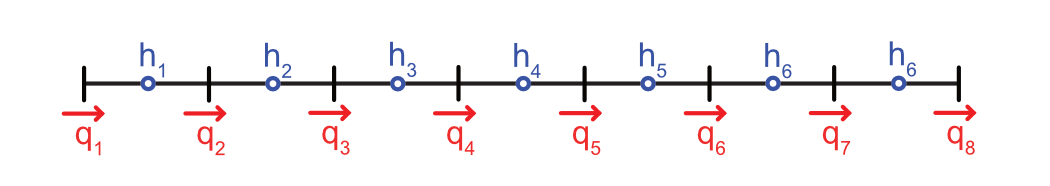

param.Nx = 55;
% param.BC = 'DD';
% param.BC = 'DD2';
param.BC = 'ND';

[xa,ha,qa,Qa] = AnalyticSolution(param);
[xFD,hFD,qFD,QFD] = FiniteDifferenceSolution(param,ha);
[xc,xf,hFV,qFV,QFV] = FiniteVolumeSolution(param,ha);

figure('position',[10 10 900 600])
subplot 131
 h = plot(xa,ha(xa),'-',xFD,hFD,'--',xc,hFV,'--'); hold on
c = get(h,'Color');
plot(rlim,ha(rlim),'o','markerfacecolor','w','markeredgecolor',c{1})
pbaspect([1 .8 1])
xlabel 'r', ylabel 'h'
legend('Analytic','FD','FV')

subplot 132
plot(xa,qa(xa),'-',xFD,qFD,'--',xf,qFV,'--'), hold on
plot(rlim,qa(rlim),'o','markerfacecolor','w','markeredgecolor',c{1})
pbaspect([1 .8 1])
xlabel 'r', ylabel 'q'
subplot 133
plot(xa,Qa(xa),'-',xFD,QFD,'--',xf,QFV,'--'), hold on
plot(rlim,Qa(rlim),'o','markerfacecolor','w','markeredgecolor',c{1})
pbaspect([1 .8 1])
xlabel 'r', ylabel 'Q'

#### Auxillary functions

function [] = set_demo_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

function [xa,ha,qa,Qa] = AnalyticSolution(param)
rw = param.rw; 
r0 = param.r0;
h0 = param.h0;
Qw = param.Qw;
H = param.H;
K = param.K;

% Analytic solution
xa = linspace(rw,r0,1e3);
ha = @(r) h0 - Qw/2/pi/H/K * log(r/r0);
qa = @(r) Qw/2/pi/H./r;
Qa = @(r) Qw+0*r;
end

%% Finite difference solution
function [xFD,hFD,qFD,QFD] = FiniteDifferenceSolution(param,ha)
rw = param.rw; 
r0 = param.r0;
h0 = param.h0;
Qw = param.Qw;
H = param.H;
K = param.K;
Nx = param.Nx;
BC = param.BC;
Aw = param.Aw;

x = linspace(rw,r0,Nx)'; dx = x(2)-x(1);
e = ones(Nx,1);
D = spdiags([-e e]/2/dx,[-1 1],Nx,Nx); 
D(1,1) = -3/2/dx; D(1,2) = 4/2/dx; D(1,3) = -1/2/dx; 
D(Nx,Nx) = 3/2/dx; D(Nx,Nx-1) = -4/2/dx; D(Nx,Nx-2) = 1/2/dx; 

D2 = spdiags([e -2*e e]/dx^2,[-1 0 1],Nx,Nx); 
R = spdiags(x,0,Nx,Nx); I = speye(Nx,Nx);
L = -K*(R*D2+D); fs = zeros(Nx,1); 

if strcmp(BC,'ND')
    L(1,:) = D(1,:); fs(1) = -Qw/Aw/K;
    B = I(Nx,:); N = I; N(:,Nx) = [];
    g = ha(r0);
elseif strcmp(BC,'DD') || strcmp(BC,'DD2')
    B = I([1;Nx],:); N = I; N(:,[1;Nx]) = [];
    g = [ha(rw);ha(r0)];
end

hFD = solve_lbvp(L,fs,B,g,N);
qFD = -K*D*hFD;
QFD = 2*pi*H*x.*qFD;
xFD = x;
end

function [x,h,q,Q,L,L_e_o] = FD_collocated(param,ha)
rw = param.rw; 
r0 = param.r0;
h0 = param.h0;
Qw = param.Qw;
H = param.H;
K = param.K;
Nx = param.Nx;
%BC = param.BC;
%Aw = param.Aw;

x = linspace(rw,r0,Nx)'; dx = x(2)-x(1);
e = ones(Nx,1);
D = full(spdiags([-e e]/2/dx,[-1 1],Nx,Nx));
D(1,1) = -1/dx; D(1,2) = 1/dx;
D(Nx,Nx-1) = -1/dx; D(Nx,Nx) = 1/dx;
% D(1,N) = -1/2; D(N,1) = 1/2;
% D = D/dx;

r = spdiags(x,0,Nx,Nx);
L = -D*r*D;

B = zeros(2,Nx); B(1,1) = 1; B(2,Nx) = 1;
I = eye(Nx); N = I(:,2:Nx-1);
g = [ha(rw); ha(r0)];

odd = [1:2:Nx]'; even = [2:2:Nx]';
P = I([odd;even],:);
L_e_o = P*L*P';
% subplot 121
% spy(L)
% title 'Standard ordering'
% subplot 122
% spy(P*L*P')
% title 'Even-odd ordering'


h = solve_lbvp(L,0,B,g,N);
q = -D*h;
Q = x.*q;

end

%% Finite volume solution
function [xc,xf,hFV,qFV,QFV] = FiniteVolumeSolution(param,ha)
rw = param.rw; 
r0 = param.r0;
h0 = param.h0;
Qw = param.Qw;
H = param.H;
K = param.K;
Nx = param.Nx;
BC = param.BC;
Aw = param.Aw;

Grid.xmin = rw; Grid.xmax = r0; Grid.Nx = Nx; Grid.geom = 'cylindrical_r';
Grid = build_grid(Grid);

[D,G,C,I,M] = build_ops(Grid);
L = -D*K*G; fs = zeros(Grid.Nx,1); fn = fs;

if strcmp(BC,'ND')
    %B = I(Grid.Nx,:); N = I; N(:,Nx) = [];
    Param.g = ha(r0-Grid.dx/2);
    fn(1) = Qw/Grid.V(1);
    Param.dof_dir = [Grid.dof_xmax];
    Param.dof_f_dir = [Grid.dof_f_xmax];
    Param.dof_neu = [Grid.dof_xmin;]; 
    Param.dof_f_neu = [Grid.dof_f_xmin];
    Param.qb = Qw/Grid.A(1);
    [B,N,fn] = build_bnd(Param,Grid,I);
    fn(1) = Qw/Grid.V(1);
elseif strcmp(BC,'DD')
%     B = I([1;Nx],:); N = I; N(:,[1;Nx]) = [];
    Param.g = [ha(rw);ha(r0)];
    Param.dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
    Param.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
    Param.dof_neu = []; Param.dof_f_neu = [];
    [B,N,fn] = build_bnd_class(Param,Grid);
elseif strcmp(BC,'DD2')
    B = I([1;Nx],:);  N = I; N(:,[1;Nx]) = [];
    Param.g = [ha(rw+Grid.dx/2);ha(r0-Grid.dx/2)];
end

hFV = solve_lbvp(L,fs+fn,B,Param.g,N);
%qFV = comp_flux(D,K,G,hFV,fs,Grid);
qFV = comp_flux(D,K,G,hFV,fs,Grid,Param);
QFV = 2*pi*Grid.xf*H.*qFV;
xc = Grid.xc;
xf = Grid.xf;
end